# Windowed, Averaged Periodograms

set(groot, 'defaultAxesFontSize',15);

% Load variables
ar7 = load("D:\AA - Windows\Benutzerdateien\OneDrive\Dokumente\MATLAB\DSP_Lab\lab7\files_lab7\ar7.mat");
ans = ar7.ans;
X = ar7.X;
clear ar7;

% Display results
ans,X

ans =         1000           1


X =    -1.1675
    1.7295
   -1.1202
   -0.8397
    0.8304
   -2.8002
   -1.2226
   -0.5582
   -1.8595
   -0.2523


% Calculate the Periodograms via spec1

L = [1, 2, 5, 10];
N = length(X);
M = N/L(1);
window = rectwin(M);
Periodogram_1 = spec1(X, L(1), rectwin(N/L(1)));
Periodogram_2 = spec1(X, L(2), rectwin(N/L(2)));
Periodogram_5 = spec1(X, L(3), rectwin(N/L(3)));
Periodogram_10 = spec1(X, L(4), rectwin(N/L(4)));

Periodogram_1_ham = spec1(X, L(1), hamming(N/L(1)));
Periodogram_2_ham = spec1(X, L(2), hamming(N/L(2)));
Periodogram_5_ham = spec1(X, L(3), hamming(N/L(3)));
Periodogram_10_ham = spec1(X, L(4), hamming(N/L(4)));

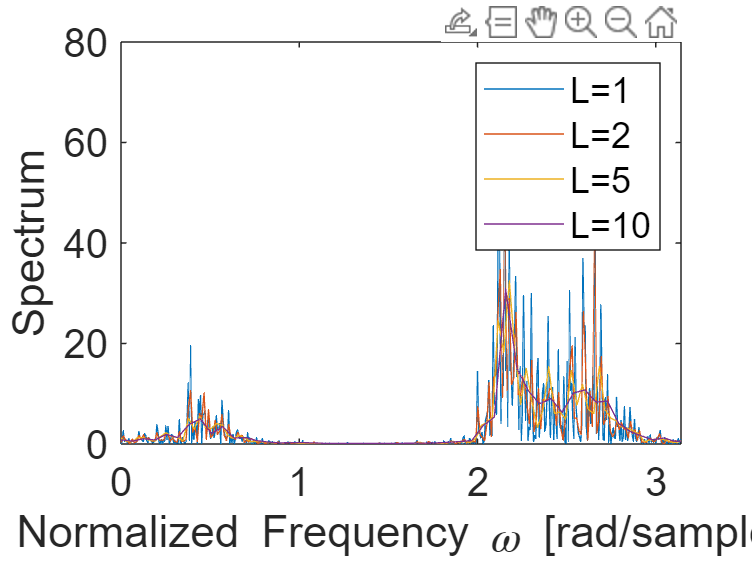

%% Figures for Periodograms
figure;
plot(linspace(0, 2*pi, length(Periodogram_1)), Periodogram_1);
hold on;
plot(linspace(0, 2*pi, length(Periodogram_2)), Periodogram_2);
hold on;
plot(linspace(0, 2*pi, length(Periodogram_5)), Periodogram_5);
hold on;
plot(linspace(0, 2*pi, length(Periodogram_10)), Periodogram_10);
hold off;
xlim([0, pi]);
xlabel("Normalized Frequency \omega [rad/sample]");
ylabel("Spectrum");
legend(["L=1", "L=2", "L=5", "L=10"]);

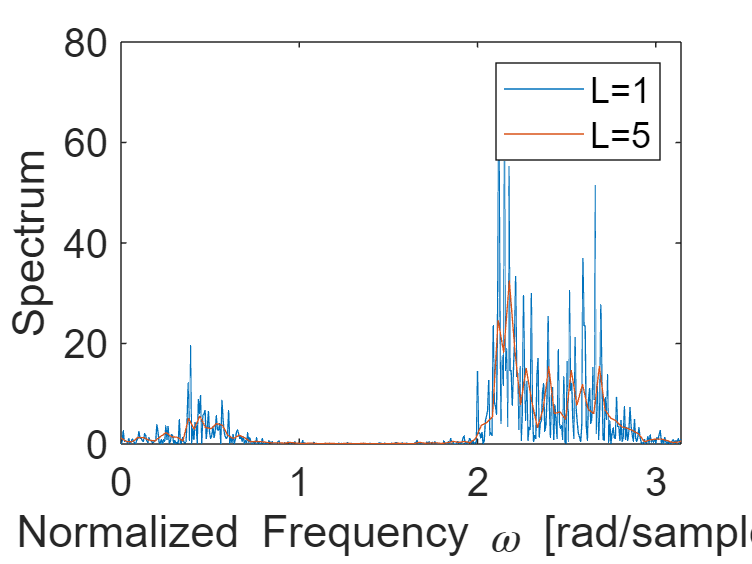


figure;
plot(linspace(0, 2*pi, length(Periodogram_1)), Periodogram_1);
hold on;
plot(linspace(0, 2*pi, length(Periodogram_5)), Periodogram_5);
hold off;
xlim([0, pi]);
xlabel("Normalized Frequency \omega [rad/sample]");
ylabel("Spectrum");
legend(["L=1", "L=5"]);

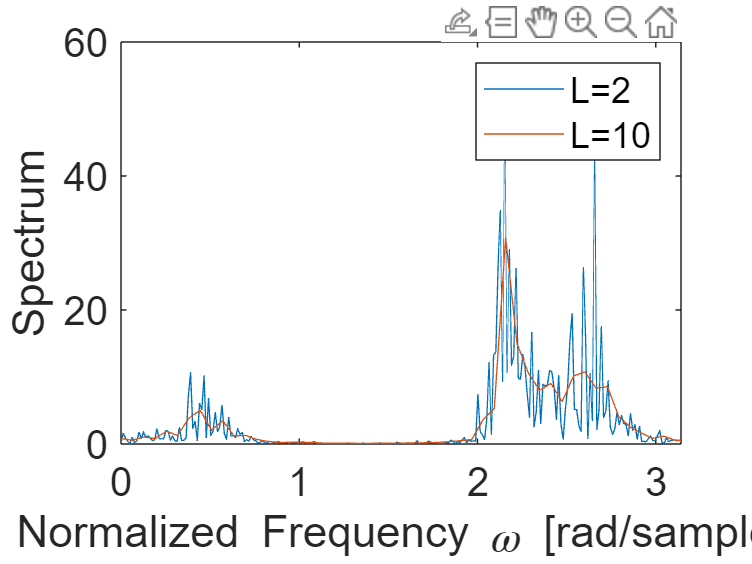


figure;
plot(linspace(0, 2*pi, length(Periodogram_2)), Periodogram_2);
hold on;
plot(linspace(0, 2*pi, length(Periodogram_10)), Periodogram_10);
hold off;
xlim([0, pi]);
xlabel("Normalized Frequency \omega [rad/sample]");
ylabel("Spectrum");
legend(["L=2", "L=10"]);

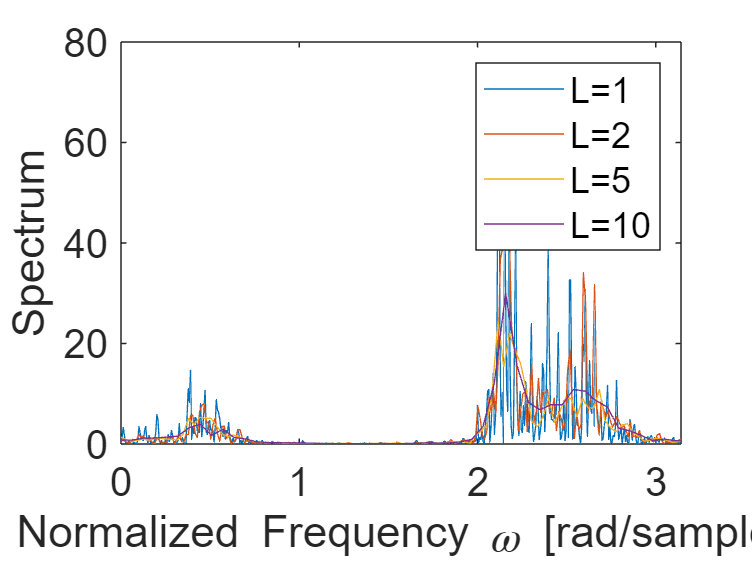



figure;
plot(linspace(0, 2*pi, length(Periodogram_1_ham)), Periodogram_1_ham);
hold on;
plot(linspace(0, 2*pi, length(Periodogram_2_ham)), Periodogram_2_ham);
hold on;
plot(linspace(0, 2*pi, length(Periodogram_5_ham)), Periodogram_5_ham);
hold on;
plot(linspace(0, 2*pi, length(Periodogram_10_ham)), Periodogram_10_ham);
hold off;
xlim([0, pi]);
xlabel("Normalized Frequency \omega [rad/sample]");
ylabel("Spectrum");
legend(["L=1", "L=2", "L=5", "L=10"]);

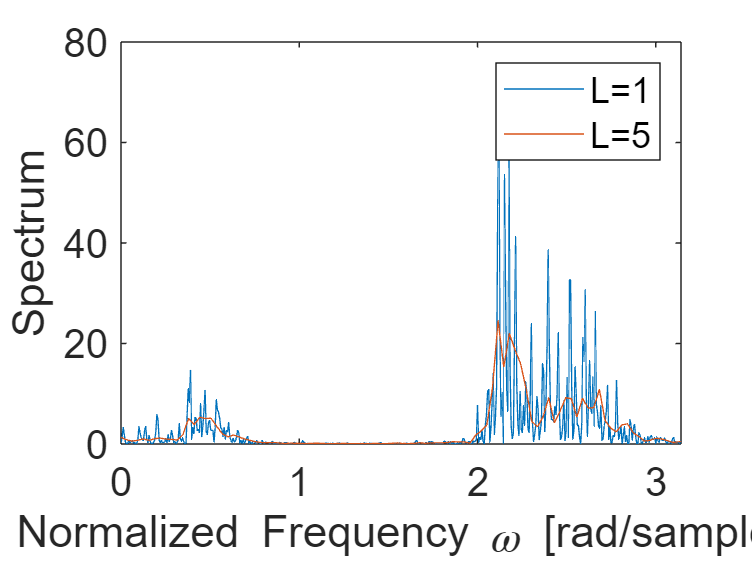


figure;
plot(linspace(0, 2*pi, length(Periodogram_1_ham)), Periodogram_1_ham);
hold on;
plot(linspace(0, 2*pi, length(Periodogram_5_ham)), Periodogram_5_ham);
hold off;
xlim([0, pi]);
xlabel("Normalized Frequency \omega [rad/sample]");
ylabel("Spectrum");
legend(["L=1", "L=5"]);

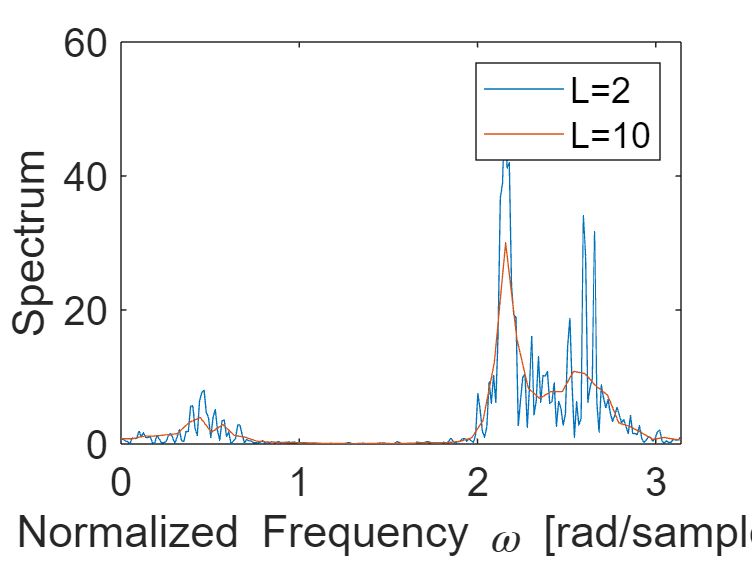


figure;
plot(linspace(0, 2*pi, length(Periodogram_2_ham)), Periodogram_2_ham);
hold on;
plot(linspace(0, 2*pi, length(Periodogram_10_ham)), Periodogram_10_ham);
hold off;
xlim([0, pi]);
xlabel("Normalized Frequency \omega [rad/sample]");
ylabel("Spectrum");
legend(["L=2", "L=10"]);

% Compute and plot the Log-Spectrum

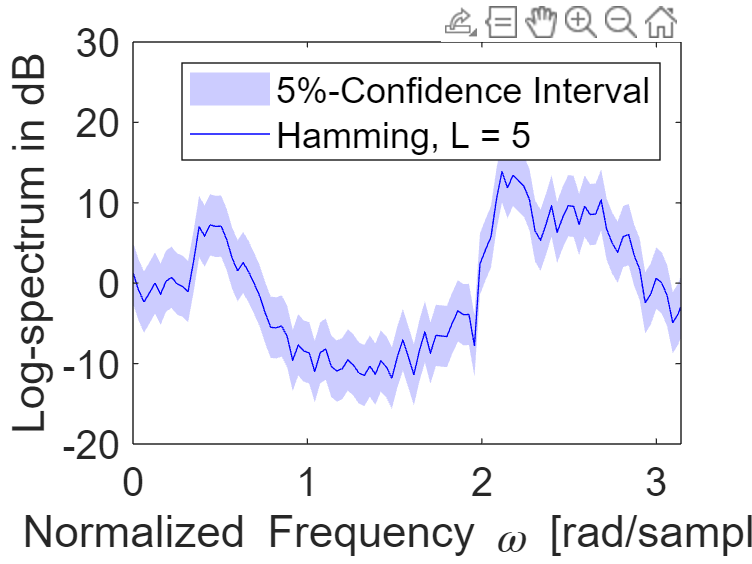

log_spec_rect = {10*log10(Periodogram_1), 10*log10(Periodogram_2), 10*log10(Periodogram_5), 10*log10(Periodogram_10)};
log_spec_ham = {10*log10(Periodogram_1_ham), 10*log10(Periodogram_2_ham), 10*log10(Periodogram_5_ham), 10*log10(Periodogram_10_ham)};

%N_alpha2 = norminv(0.975);
N_alpha2 = 1.96;
confidence_intervall = [log_spec_ham{3}-10*log10(exp(N_alpha2/sqrt(5))), log_spec_ham{3}+10*log10(exp(N_alpha2/sqrt(5)))];

% figure;
% plot(log_spec_ham{3});
% hold on;
% plot(confidence_intervall(:,1));
% hold on;
% plot(confidence_intervall(:,2));
% hold off;

w_rad = linspace(0, 2*pi, 200);

x_conf = [w_rad w_rad(end:-1:1)];
y_conf = [confidence_intervall(:,1); confidence_intervall(end:-1:1,2)];
figure;
plt = fill(x_conf, y_conf, 'red');
plt.FaceColor = [0.8 0.8 1];
plt.EdgeColor = 'none';
hold on;
plot(w_rad, log_spec_ham{3}, 'b');
hold off;
xlim([0, pi]);
ylim([-20, 30]);
xlabel("Normalized Frequency \omega [rad/sample]");
ylabel("Log-spectrum in dB")
legend(["5%-Confidence Interval","Hamming, L = 5"]);